clear, close all, clc


- Normal distribution is a bell shaped, symmetrical distributions. It is presented by the letter Z as defined below.


$$Z=\frac{X-\mu }{\sigma }$$
 

X represents a random varible from a normal distribution. Based on that, $\sigma$ represents the standard deviation of the curve, and $\mu$ represents the mean.

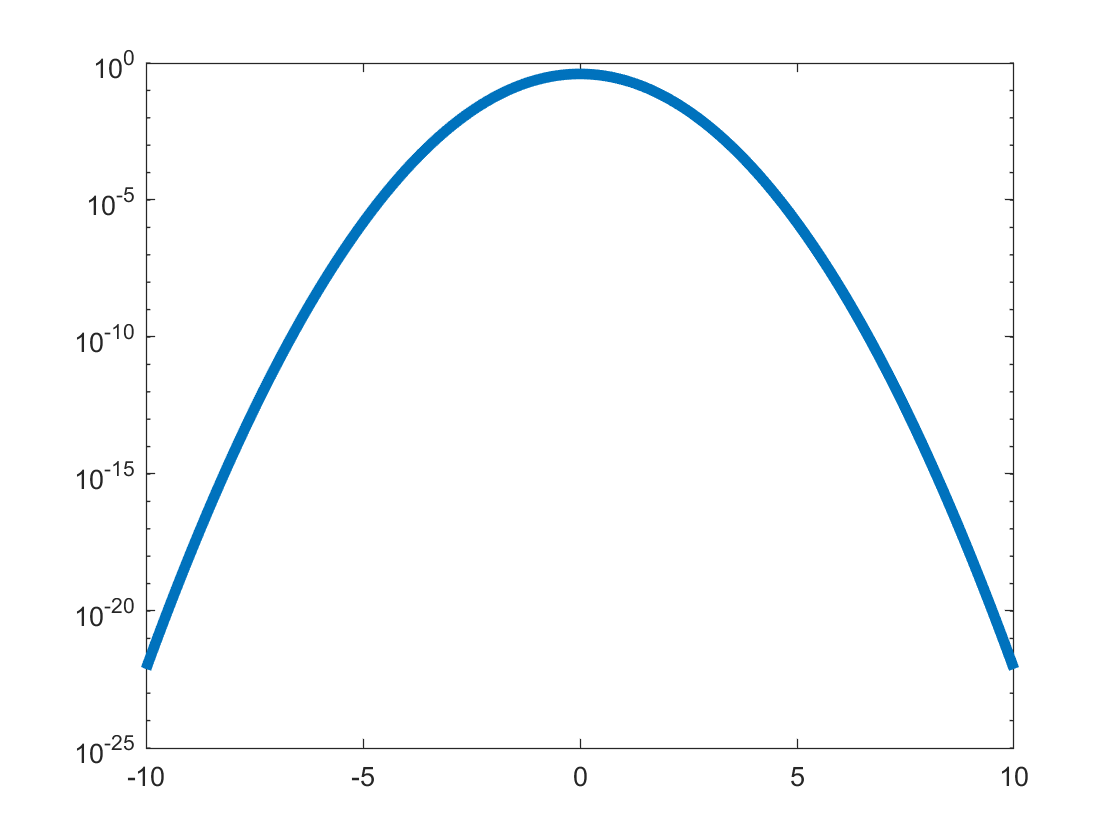

x = linspace(-10,10,1000);
  gaus = makedist("Normal",'mu',0,'sigma',1); 
semilogy(x,pdf(gaus,x),"LineWidth",4);

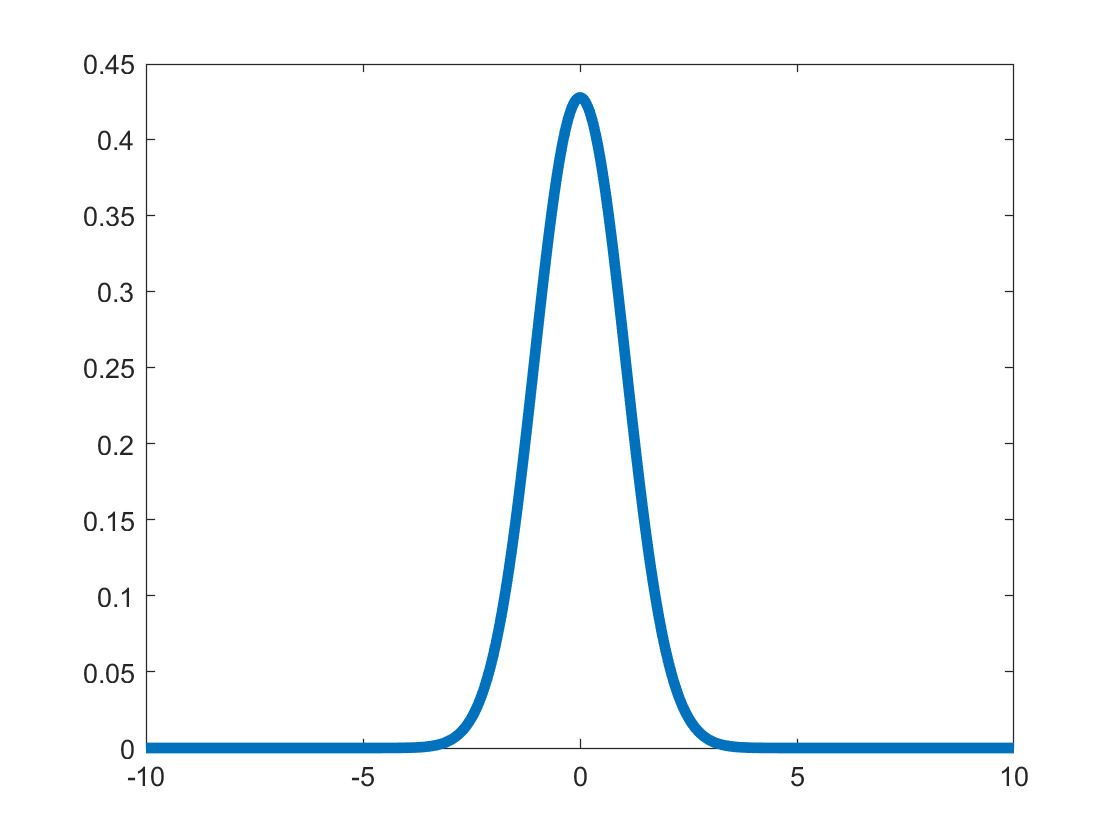


Norm_Int = erf(pdf(gaus,x));
plot(x,Norm_Int, "LineWidth",4)

Here I am using $\phi \left(x\right)=\frac{2}{\sqrt{\pi }}\int_0^x e^{-\frac{t^2 }{2}} \textrm{dt}$

sig_val = erfinv(pdf(gaus,x));
Sig = 1

Sig = 1

PercentWithin_Sig = 1-sig_val(500+50*Sig)

PercentWithin_Sig = 0.7801

2. Rayleigh distributions are used 

x = linspace(0,10,100000);
b =0.8

b = 0.8000

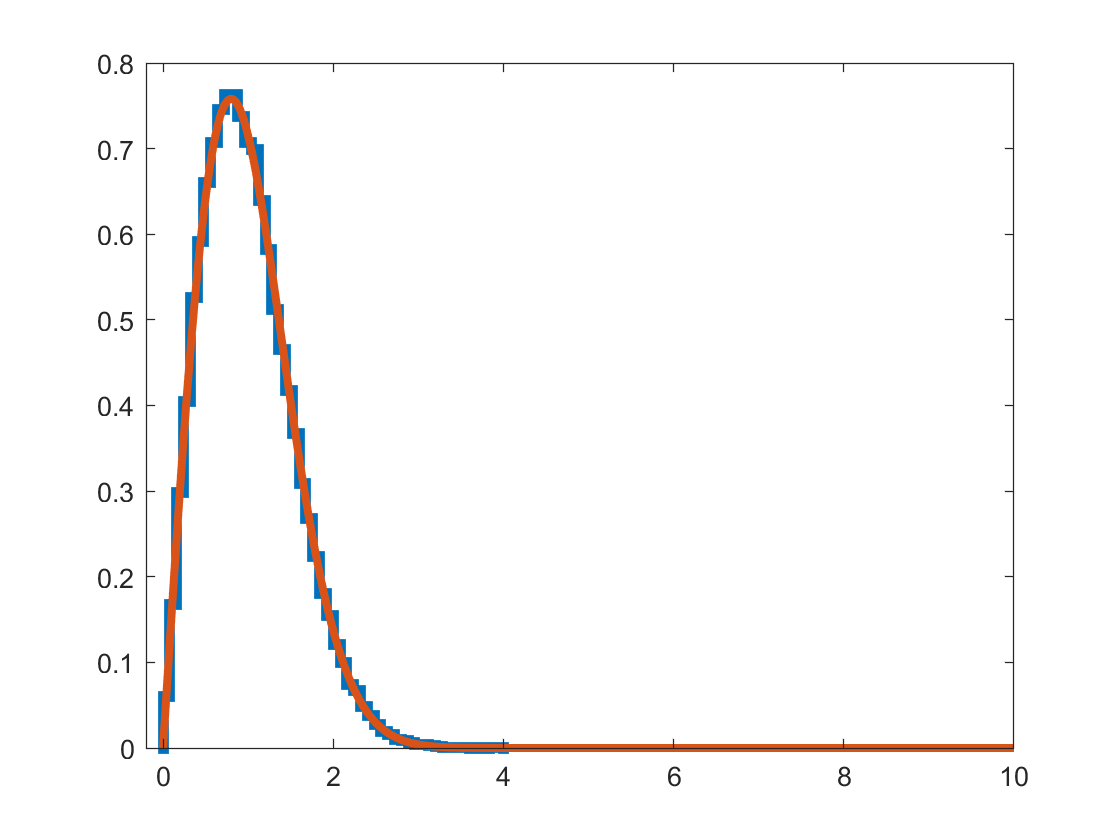

d = random('Rayleigh', b, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',4,"Normalization","pdf")
hold on 
rayl = makedist("Rayleigh",b);
semilogy(x,pdf(rayl,x),"LineWidth",3);